## Problem Distance Protection 1: Three-phase

Consider the simple 13.8 kV system represented by the one-line diagram below. 

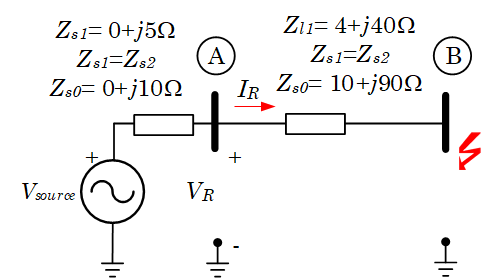

Verify the distance calculation for a 

**(a) three-phase, **

(b) phase-to-phase, and

(c) phase-to-ground faults.

Created by: Professor Francisco Gonzalez-Longatt, March 2020, [fglongatt@fglongatt.org](mail: fglongatt@fglongatt.org) 

#GitHub: [https://github.com/fglongatt/PowerSystemProtections](https://github.com/fglongatt/PowerSystemProtections) 

#ResearchGate: [https://www.researchgate.net/project/Power-System-Protection-13](https://www.researchgate.net/project/Power-System-Protection-13) 

clc
clear all

System data

Vll = 13.8e3;        % Vll: Nominal line-to-line voltage in Volts
Vln = Vll / sqrt(3); % Vlb: Nomianl line to neutral voltage in Volts
VT = Vln;

The sequence impedance of the source (Zs2 = Zs1);

Zs1 = 0 + 5*i;
Zs0 = 0 + 10*i

Zs0 = 0.0000 + 10.0000i

The sequence impedance of the line (Zl2 = Zl1);

Zl1 = 4 + 40*i

Zl1 = 4.0000 + 40.0000i

Zl0 = 10 + 90*i

Zl0 = 10.0000 + 90.0000i

### Three-phase fault

Three-phase, only the positive-sequence current exists, and is also the phase a current

Ia = Vln / ( Zs1 + Zl1);
fprintf(' Ia = (%5.5f ∠ %5.5f°) A', abs(Ia), angle(Ia)*180/pi)

 Ia = (176.35873 ∠ -84.92039°) A

fprintf(' Ia = (%5.5f + j%5.5f) A', real(Ia),imag(Ia))

 Ia = (15.61476 + j-175.66610) A

The phase a voltage at the relay location is given by

VT = Vln;
VRa1 = VT - Zs1 * Ia

VRa1 = 7.0891e+03 - 7.8074e+01i

fprintf(' Va = (%5.5f ∠ %5.5f°) A', abs(VRa1), angle(VRa1)*180/pi)

 Va = (7089.53311 ∠ -0.63099°) A

fprintf(' Va = (%5.5f + j%5.5f) A', real(VRa1),imag(VRa1))

 Va = (7089.10320 + j-78.07382) A

The fault impedance (Zf) seen by the relay in this case is

Zf = VRa1 / Ia;
fprintf(' Zf = (%5.5f ∠ %5.5f°) Ω', abs(Zf), angle(Zf)*180/pi)

 Zf = (40.19950 ∠ 84.28941°) Ω

fprintf(' Zf = (%5.5f + j%5.5f) Ω', real(Zf),imag(Zf))

 Zf = (4.00000 + j40.00000) Ω